# create real world for animation

clear; close all;

## setting up real world

### real world boundaries

pitch_max    = deg2rad(90);
pitch_min    = deg2rad(-90);
position_max = 1.5;
position_min = -0.25;

### algebraic model of Chabo

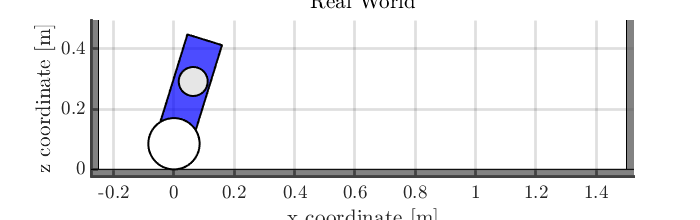

% Geometric sizes of the TWIPR polygon
chabo_height = 0.36;
chabo_width  = 0.12;
chabo_wheel_radius = 0.085;
% Setup the vertices and the polygon of the TWIPR using the MATLAB-function
% "polyshape"
chabo_vertices_x_coordinates = [chabo_width/2,...
                              chabo_width/2,...
                              -chabo_width/2,...
                              -chabo_width/2];
chabo_vertices_z_coordinates = [chabo_wheel_radius,...
                              chabo_wheel_radius + chabo_height,...
                              chabo_wheel_radius + chabo_height,...
                              chabo_wheel_radius];
chabo_polygon = polyshape(chabo_vertices_x_coordinates, chabo_vertices_z_coordinates);


real_world = CRealWorld(pitch_max, pitch_min, position_max, position_min, chabo_polygon);
figure('Position', [0, 0, 700, 220]);
real_world.drawWorld();
real_world.drawRealChabo(0.3, 0, 'blue');

% real_world.drawWorld();
n = 1:0.02:150;
pitch_traj = sin(n);
pos_traj   = n ./100;
% animate_movement_real_world(real_world, pitch_traj, pos_traj);
save('99_animation\02_data\real_world.mat','real_world');